# ปัญหาวันที่ 2

## เป้าหมาย

- สามารถระบุตำแหน่งของ stamping event ได้

- สามารถจำแนก stamping event ได้ (N/F)

- สามารถอธิบายแนวทางในการหาตำแหน่ง event การตัด segment และการจำแนก event ได้

## ข้อกำหนด

- ใช้ไฟล์ที่อยู่ใน folder Day2 ในการ train model โดยต้องตัดเองและเลือกความยาวในการตัดเอง

## ผลลัพธ์ที่ต้องการ

- โปรแกรมจะอ่านไฟล์ที่กำหนด แล้วแสดงผลลัพธ์เป็นตำแหน่งของ event และสถานะเป็น N (normal) หรือ F (faulty) บรรทัดละ event

- ตำแหน่งของ event จะเป็นลำดับของ sample นับตั้งแต่พบสัญญาณ SYNC โดยอนุญาตให้คลาดเคลื่อนได้ +/- 14400 sample (0.3 วินาที)

- รูปแบบการแสดงผลคล้ายดังนี้

102230 N

197740 F

275941 F

...

## โครงโปรแกรม

สามารถเขียนใหม่ได้ทั้งหมด ไม่จำเป็นต้องใช้ตามนี้

ตอนตรวจขั้นสุดท้าย จะต้องเปลี่ยนชื่อไฟล์ด้านล่างนี้ให้เป็นไฟล์ที่กำหนด

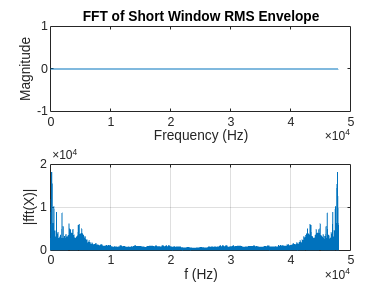

[audioData, Fs] = audioread('Day2/Faulty2.wav');

shortWinLength = round(0.3 * Fs);
longWinLength = round(2.0 * Fs);

shortRMS = dsp.MovingRMS(shortWinLength);
longRMS = dsp.MovingRMS(longWinLength);

env1 = shortRMS(audioData);
env2 = longRMS(audioData);

shortOffset = round(shortWinLength/2);
longOffset = round(longWinLength/2);

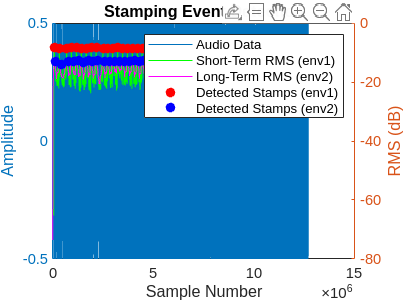

% Calculate thresholds for env1 and env2
threshold1 = mean(env1) + 1.99 * std(env1); % Adjust multiplier based on sensitivity
threshold2 = mean(env2) + 0.4 * std(env2);

% Find peaks above thresholds
[peaks1, locs1] = findpeaks(env1, 'MinPeakHeight', threshold1, 'MinPeakDistance', shortWinLength + 1e5);
[peaks2, locs2] = findpeaks(env2, 'MinPeakHeight', threshold2, 'MinPeakDistance', longWinLength + 6.9e4);

% Plot the audio data and envelope with detected events
figure;
yyaxis left;
plot(audioData);
ylabel('Amplitude');
hold on;

yyaxis right;
plot(mag2db(env1(shortOffset:end)), 'g-');
plot(mag2db(env2(longOffset:end)), 'm-');

% Mark detected peaks (stamping events)
yyaxis right;
plot(locs1, mag2db(peaks1), 'ro', 'MarkerFaceColor', 'r'); % Stamps detected by env1
plot(locs2, mag2db(peaks2), 'bo', 'MarkerFaceColor', 'b'); % Stamps detected by env2

legend('Audio Data', 'Short-Term RMS (env1)', 'Long-Term RMS (env2)', 'Detected Stamps (env1)', 'Detected Stamps (env2)');
title('Stamping Event Detection');
xlabel('Sample Number');
ylabel('RMS (dB)');
hold off;

size_file = size(locs1);
for i = 1:size_file(1)

        filename = sprintf("Train/Faulty/Faulty%d.wav", 52 + i);  % Use %d to insert the loop index
        % Write the audio data to the WAV file
        audiowrite(filename, audioData(locs1(i) - 1.2e4:locs2(i)), Fs);
end


player = audioplayer(audioData(locs(2) - 1e4:locs(2) + 1e4), Fs); % must specify correct sampling rate
play(player);